# **Clustering avec la méthode des k-means**

**1)** **Préparation des données** : les fonctions prennent en entrée une liste de chaînes et les convertissent en une matrice binaire où chaque ligne représente une observation et chaque colonne un élément unique.

**2) Détermination du nombre optimal de clusters** : méthode de la silhouette pour déterminer le nombre optimal de clusters (k) en testant différentes valeurs de k.

**3) Application de l'algorithme K-means** : le clustering est réalisé avec l'algorithme K-means sur la matrice binaire.

**4) Analyse et visualisation des résultats** : génèration de plusieurs visualisations et métriques pour évaluer la qualité du clustering.

**K-means**

Objectif : Regrouper des points de données en k groupes (ou clusters) selon leur proximité dans l’espace

- **Choisir k** : le nombre de clusters souhaités (généralement entre 2 et 10)

- **Initialiser aléatoirement** k centres qu'on va appeler centroïdes

- **Attribuer chaque point** au centre le plus proche selon la distance euclidienne

- **Mettre à jour les centroïdes** : recalculer le centre de chaque cluster

- **Répéter** les étapes 3 et 4 jusqu’à ce que les centroïdes ne bougent plus (ou très peu)

**PCA**

Objectif : Transformer des données très dimensionnelles en quelques dimensions importantes sans trop perdre d’informations

- **Centrez les données** : on soustrait la moyenne pour que tout parte de zéro

- **Calculez la matrice de covariance** : pour voir comment les variables varient ensemble

- **Décomposez la matrice** : on extrait les vecteurs propres et leurs valeurs propres 

- **Projetez les données** sur ces nouveaux axes (généralement on garde les 2 ou 3 premières dimensions, qui capturent le plus de variance). Sur un nuage de points en 3D, le PCA te trouve le meilleur plan 2D sur lequel projeter les points pour qu’on garde un maximum d’informations.

Synergies (matrice W)


Le nombre optimal de clusters selon le score silhouette est k = 10 (score = 0.8182)

 Résumé des Clusters de Synergies (k-means):
--------------------------------------

 Cluster 1 (n = 8):
----------------------------
• A22_W1,A22_W2
• A4_W1,A4_W2
• A5_W1,A5_W2
• A10_W1,A10_W2
• A12_W1,A12_W2
• A14_W1,A14_W2
• A15_W1,A15_W2
• A17_W1,A17_W2

 Cluster 2 (n = 1):
----------------------------
• A24_W1,A24_W2

 Cluster 3 (n = 1):
----------------------------
• A3_W1,A3_W2

 Cluster 4 (n = 1):
----------------------------
• A18_W1,A18_W2


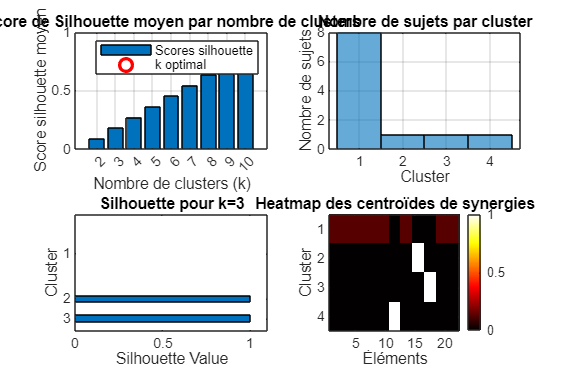

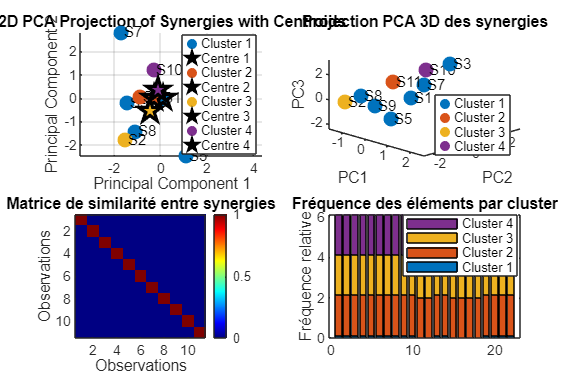


 Évaluation de la qualité du clustering:
--------------------------------------
• Score de Silhouette: 0.2727 (idéalement proche de 1)
• Indice Davies-Bouldin: 0.8819 (plus petit = meilleur)
• Indice Calinski-Harabasz: 1.0000 (plus grand = meilleur)
• Nombre optimal de clusters selon silhouette: 10

 Distances moyennes intra-cluster (Jaccard):
• Cluster 1: 1.0000
• Cluster 2: 0.0000
• Cluster 3: 0.0000
• Cluster 4: 0.0000


synergies = {'A22_W1,A22_W2', 'A3_W1,A3_W2', ...
             'A4_W1,A4_W2', 'A5_W1,A5_W2', ...
             'A10_W1,A10_W2', 'A12_W1,A12_W2', ...
             'A14_W1,A14_W2', 'A15_W1,A15_W2', ...
             'A17_W1,A17_W2', 'A18_W1,A18_W2',...
             'A24_W1,A24_W2'};

[clusteredSynergies, clusterResults] = synergyStringClustering_kmeans(synergies);

Activation temporelle (matrice H)


Le nombre optimal de clusters selon le score silhouette est k = 10 (score = 0.8182)

 Résumé des Clusters de activations (k-means):
--------------------------------------

 Cluster 1 (n = 2):
----------------------------
• A4_H1,A4_H2
• A17_H1,A17_H2

 Cluster 2 (n = 1):
----------------------------
• A24_H1,A24_H2

 Cluster 3 (n = 1):
----------------------------
• A3_H1,A3_H2

 Cluster 4 (n = 1):
----------------------------
• A18_H1,A18_H2

 Cluster 5 (n = 1):
----------------------------
• A12_H1,A12_H2

 Cluster 6 (n = 1):
----------------------------
• A22_H1,A22_H2

 Cluster 7 (n = 1):
----------------------------
• A5_H1,A5_H2

 Cluster 8 (n = 1):
----------------------------
• A14_H1,A14_H2

 Cluster 9 (n = 1):
----------------------------
• A15_H1,A15_H2

 Cluster 10 (n = 1):
----------------------------
• A10_H1,A10_H2


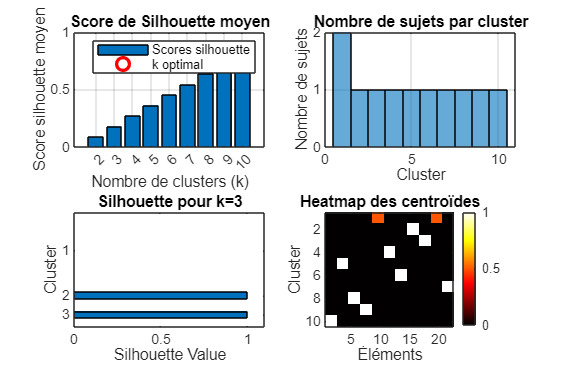

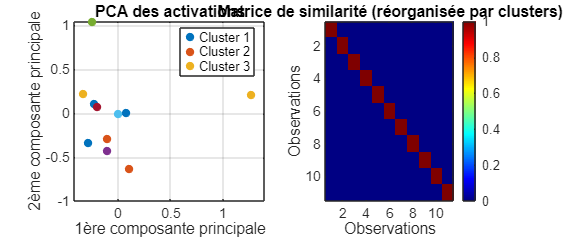


 Évaluation de la qualité du clustering:
--------------------------------------
• Score de Silhouette: 0.8182 (idéalement proche de 1)
• Indice Davies-Bouldin: 0.5774 (plus petit = meilleur)
• Indice Calinski-Harabasz: 1.0000 (plus grand = meilleur)
• Nombre optimal de clusters selon silhouette: 10


 activations = {'A22_H1,A22_H2', 'A3_H1,A3_H2', ...
                'A4_H1,A4_H2', 'A5_H1,A5_H2', ...
                'A10_H1,A10_H2', 'A12_H1,A12_H2', ...
                'A14_H1,A14_H2', 'A15_H1,A15_H2', ...
                'A17_H1,A17_H2', 'A18_H1,A18_H2',...
                'A24_H1,A24_H2'};

 [clusteredactivations, clusterResults] = activationsStringClustering_kmeans(activations);